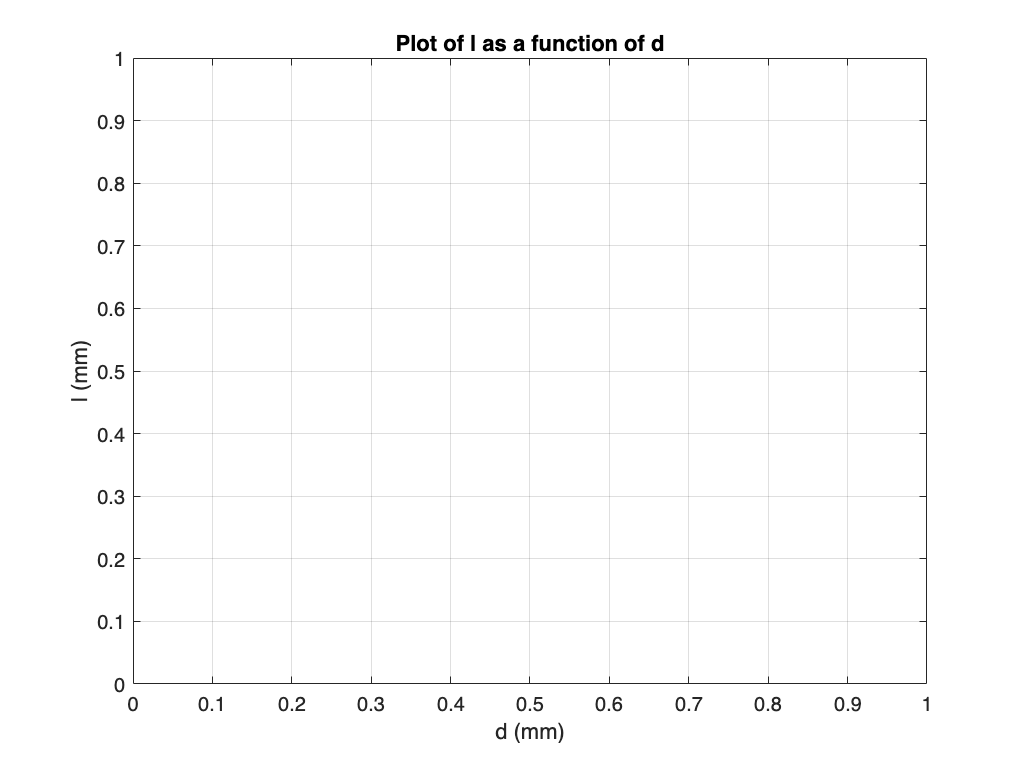

clc; clear; close all;

% Given parameters
a = 200; % mm
d_vals = 30:10:500; % mm
d_min = 30; % mm
d_max = 500; % mm

% Compute x_max boundary
x_max = d_max - a;

% Compute alpha within valid range
alpha_max1 = asin((x_max / 2) / ((a / 2) + d_max));
alpha_max2 = asin((a / 2) / ((a / 2) + d_min));
alpha = double(min(alpha_max1, alpha_max2) * 0.95); % Choose a bit smaller alpha

% Precompute trigonometric values
sin_alpha = sin(alpha);
cos_alpha = cos(alpha);

% Initialize variables
x = x_max; % Start with max valid x
number = 0; % Counter for adjusting x if constraints are violated
l_vals = zeros(size(d_vals)); % Store l values
x_vals = zeros(size(d_vals)); % Store x values

% Iterate over d values
for i = 1:length(d_vals)
    d = d_vals(i);
    
    while true
        % Adjust x at the beginning of the iteration
        x = x_max - number;

        % Recalculate everything when x is updated
        beta = acos((x / 2) / (a / 2 + d_max / 2));
        y2 = ((x / 2) * tan(beta)) + d_max / 2;

        % Compute l_max for current x
        l_func_max = @(l) (1 / cos_alpha) * (y2 - d_min / 2 - sin(acos((x - 2 * l * sin_alpha) / (a + d_min))) * (a / 2 + d_min / 2)) - l;
        l_max = fsolve(l_func_max, 50, optimset('Display', 'off')); % Solve for l_max
        x_min = 2 * l_max * sin_alpha + a + d_min; % Compute x_min

        % Ensure x_min <= x <= x_max
        if x_min <= x && x <= x_max
            % Solve for l using fsolve
            l_func = @(l) (1 / cos_alpha) * (y2 - d / 2 - sin(acos((x - 2 * l * sin_alpha) / (a + d))) * (a / 2 + d / 2)) - l;
            l_guess = 50; % Initial guess
            options = optimset('Display', 'off'); % Suppress fsolve output
            [sol_l, fval, exitflag] = fsolve(l_func, l_guess, options);

            % Store valid results or break if no solution
            if exitflag > 0
                l_vals(i) = sol_l;
                x_vals(i) = x;
                break; % Valid solution found, proceed to next d
            else
                l_vals(i) = NaN;
                x_vals(i) = NaN;
                break; % No solution, break to next d
            end
        else
            % Constraint violated → Adjust x and restart calculations
            number = number + 1; % Increment the counter
            if x < x_min  % If x goes below the limit, stop iteration
                l_vals(i) = NaN;
                x_vals(i) = NaN;
                break;
            end
        end
    end
end

% Plot l as a function of d
figure;
plot(d_vals, l_vals, 'b-o', 'LineWidth', 1.5);
xlabel('d (mm)');
ylabel('l (mm)');
title('Plot of l as a function of d');
grid on;


% Display results for d = 500
disp('Results for d = 500 mm:');

Results for d = 500 mm:


disp(['l = ', num2str(l_vals(end))]);

l = NaN


disp(['x = ', num2str(x_vals(end))]);

x = NaN
